# Working with energy data

This live script extracts data from the energy production and demand in Denmark in the past 5 years and performs an energy balance on the possibility of offshore storage. The first part of the work is done based on simple energy balance and the second parts looks into the subsurface energy storage.

## Plotting the energy data

There is an script for plotting the energy data, that is used as shown in the following example

date1 = '2021-01-01';
date2 = '2021-01-20';
d = extract_elect_data(date1, date2);
d.HourDK = datetime(d.HourDK, 'Format', 'yyyy-MM-dd''T''HH:mm:ss');

The above script extracts the data, that is plotted by

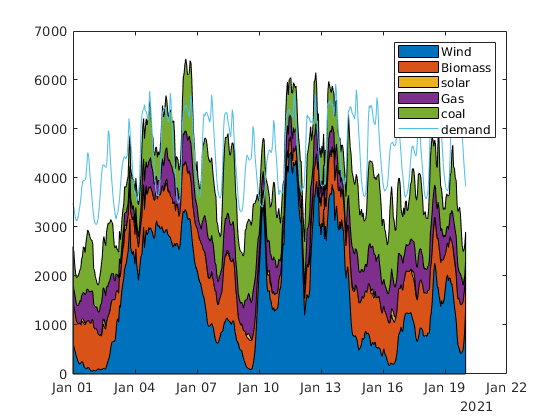

h = area(d.HourDK, [d.OnshoreWindPower+d.OffshoreWindPower d.Biomass d.SolarPower d.FossilGas d.FossilHardCoal]); 
hold on; 
plot(d.HourDK, d.TotalLoad)
legend('Wind', 'Biomass', 'solar', 'Gas', 'coal', 'demand')
hold off

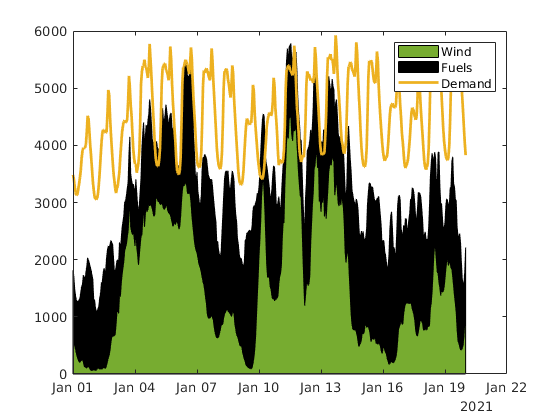


h = area(d.HourDK, [d.OnshoreWindPower+d.OffshoreWindPower d.FossilGas+d.FossilHardCoal+d.FossilOil]);
h(1).FaceColor=[0.4660 0.6740 0.1880];
h(2).FaceColor='k';
hold on; 
plot(d.HourDK, d.TotalLoad, 'LineWidth', 2); 
legend('Wind', 'Fuels', 'Demand'); 
hold off

# The future energy balance

In the near future, Denmark is going to have its windfarm capacity quadruppled. This will potentially remove the fossil fuel power plants. In practice, the production is fluctuating and sometimes, there won't be enough electricity if the wind is slow. At night and during low demand periods, there will be too much electricity. The solution is to "flatten the curve". Let's have a look at the electricity demand and the quadruppled wind electricity supply:

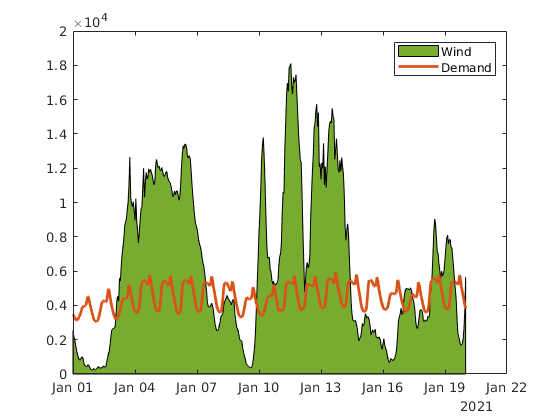

h = area(d.HourDK, 4*(d.OnshoreWindPower+d.OffshoreWindPower)); 
h(1).FaceColor=[0.4660 0.6740 0.1880];
hold on; 
plot(d.HourDK, d.TotalLoad, 'LineWidth', 2); 
legend('Wind', 'Demand'); 
hold off

Countries plan their electricity production based on "unavailabilities" and "shortages" because a pregnant lady in the delivery room cannot synchronise her due time with the time that the wind starts blowing. I chose this methaphor because it is the most amazing and scariast scene that I've seen in my life.

## The reality

In practice, the surplus electricity is going to be so cheap that the producer has to pay to get rid of it.

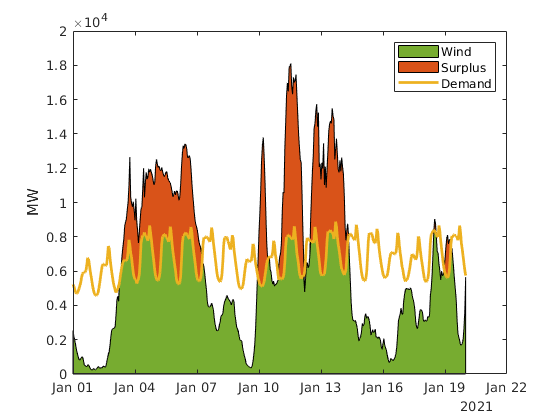

new_elec = 4*(d.OnshoreWindPower+d.OffshoreWindPower);
demand = 1.5*d.TotalLoad;
surplus_elec = new_elec-demand;
new_elec(new_elec>demand) = demand(new_elec>demand);
surplus_elec(surplus_elec<0) = 0;
shortage_elec = demand-new_elec;
h = area(d.HourDK, [new_elec surplus_elec]); 
h(1).FaceColor=[0.4660 0.6740 0.1880];
hold on; 
plot(d.HourDK, demand, "LineWidth", 2);
ylabel('MW')
legend('Wind', 'Surplus', 'Demand');
hold off

## How to address it?

The way to address it is to take the surplus, store it somewhere, and consume it when there is a shortage:

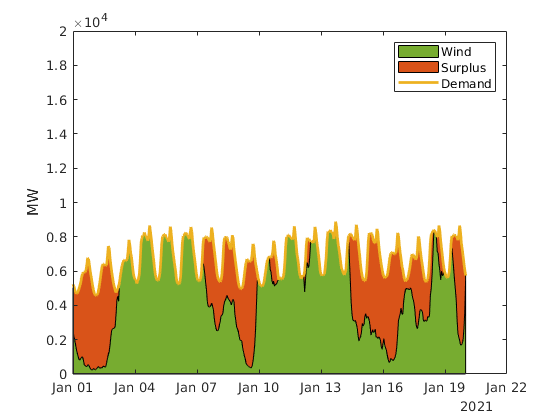

h = area(d.HourDK, [new_elec shortage_elec]);
h(1).FaceColor=[0.4660 0.6740 0.1880];
hold on; 
plot(d.HourDK, demand, 'LineWidth', 2);
ylabel('MW')
legend('Wind', 'Surplus', 'Demand'); 
ylim([0 2e4]);
hold off

And there might still be some extra for other applications, e.g. creating liquid fuels.

## Let's integrate

We can integrate the amount of surplus and unavailable electricity:

date_num = datenum(d.HourDK);
average_shortage = trapz(date_num, shortage_elec)/(date_num(end)-date_num(1))

average_shortage = 2.0960e+03

average_surplus = trapz(date_num, surplus_elec)/(date_num(end)-date_num(1))

average_surplus = 1.8517e+03

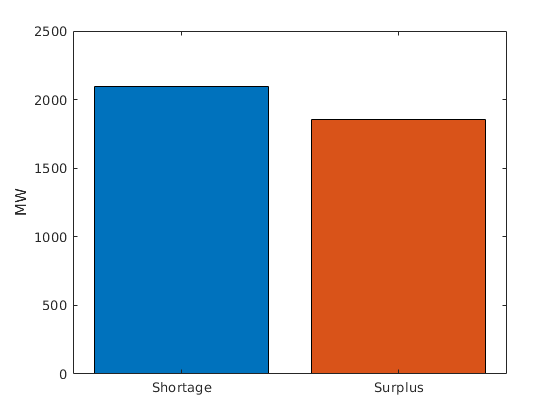

b = bar(categorical({'Surplus', 'Shortage'}), [average_surplus, average_shortage]); 
b.FaceColor = 'flat'; 
b.CData(2, :) = [0.8500 0.3250 0.0980]; 
ylabel('MW')

This means that only less than 30% of the surplus electricity is required to fill the gap created by the shortage of wind. There are several ways of storing the electricity by converting it to different forms of physical or chemical energy. The next question is, when the energy conversion is done, how and where the converted storable form can be kept?

# A 6-month view

The above figures only look at the month of January 2021. Let's have a look a longer period of time, e.g. six month to one year and compare the surplus and shortage. This time, naturally, I have written a function:

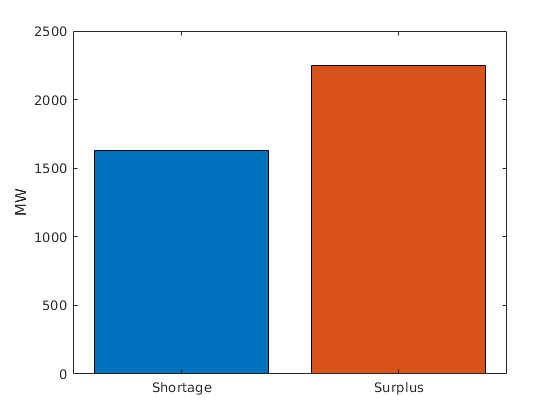

date_begin = '2020-05-01';
date_end = '2021-01-20';
d_long = extract_elect_data(date_begin, date_end);
d_long.HourDK = datetime(d_long.HourDK, 'Format', 'yyyy-MM-dd''T''HH:mm:ss');
future_demand = 1.5; % including 50% increase of demand for heating and cars
future_capacity = 4.0; % windmill capacity will be quadruppled
[wind_elec, elec_demand, surplus, shortage] = extract_surplus(d_long, future_capacity, future_demand);

% calculate the average surplus and shortage
surplus_ave = average_values(d_long.HourDK, surplus);
shortage_ave = average_values(d_long.HourDK, shortage);

b = bar(categorical({'Surplus', 'Shortage'}), [surplus_ave, shortage_ave]); 
b.FaceColor = 'flat'; 
b.CData(2, :) = [0.8500 0.3250 0.0980]; 
ylabel('MW')

## Other plots for the report

Here, I will have to visualize the future supply and demand of electricity similar to above cases but for several months:

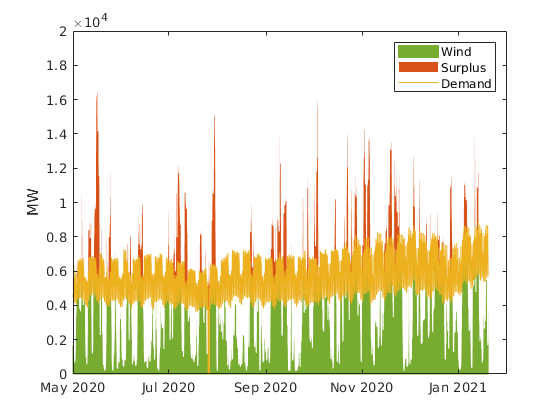

% visualize demand, surplus, and deficit
h = area(d_long.HourDK, [wind_elec surplus]); 
h(1).FaceColor=[0.4660 0.6740 0.1880];
h(1).EdgeColor = [0.4660 0.6740 0.1880];
h(2).FaceColor = [0.8500 0.3250 0.0980];
h(2).EdgeColor= 'w'; %[0.8500 0.3250 0.0980];
hold on; 
plot(d_long.HourDK, elec_demand, "LineWidth", 0.5);
ylabel('MW')
legend('Wind', 'Surplus', 'Demand');
hold off

## Looking at the average values versus time

Similar to the concept of repsetative elementary volume in porous media, I have calculated the average supply and demand versus the time period and have shown the results below:

N_remove = 24;
N_data = height(d_long)-N_remove; % remove N_remove hours from the data to make it more reliable
t = datenum(d_long.HourDK);
surplus_cumsum = cumsum(0.5*(surplus(2:end)+surplus(1:end-1)).*(t(2:end)-t(1:end-1)));
shortage_cumsum = cumsum(0.5*(shortage(2:end)+shortage(1:end-1)).*(t(2:end)-t(1:end-1)));
surplus_ave_t = surplus_cumsum./(t(2:end)-t(1));
shortage_ave_t = shortage_cumsum./(t(2:end)-t(1));
% surplus_ave_t = zeros(N_data, 1);
% shortage_ave_t = zeros(N_data, 1);
% for i = 1:N_data
%     surplus_ave_t(i) = average_values(d_long.HourDK(1:i+N_remove), surplus(1:i+N_remove));
%     shortage_ave_t(i) = average_values(d_long.HourDK(1:i+N_remove), shortage(1:i+N_remove));
% end

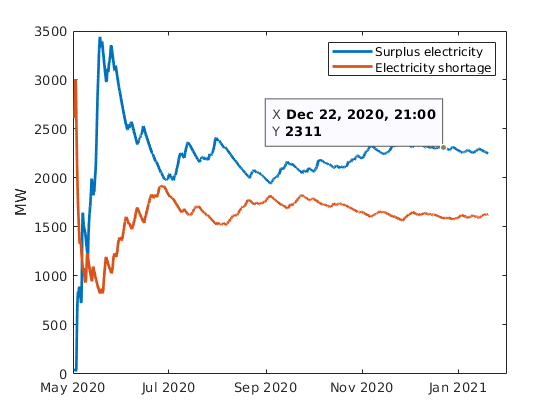

plot(d_long.HourDK(N_remove+1:end), surplus_ave_t(N_remove:end), d_long.HourDK(N_remove+1:end), shortage_ave_t(N_remove:end), 'LineWidth', 2); 
ylabel('MW');
legend('Surplus electricity', 'Electricity shortage');

## Justification

The above figure explains why we need to invest in large scale energy storage. If we look only at one or two months, we obtain an unrealistic picture of supply and demand. As we go further in time, two important number emerge: a constant average value of surplus and a constant shortage of electricity. The plan should be to provide around 1000 MW of electricity and also use the leftover to produce some synthetic fuel.

# Scale

The scale of storage must be determined by the largest deficit. The deficit between May 2020 to Januray 2021 is visualized in the following figure:

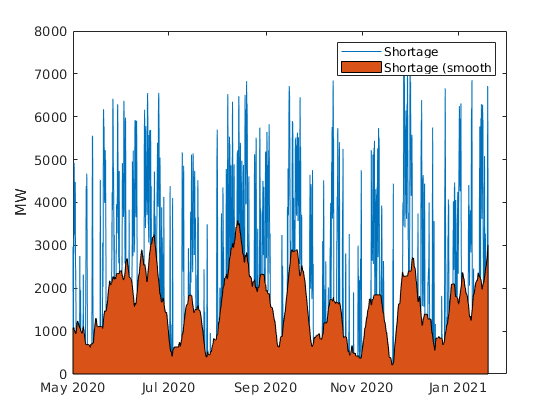

plot(d_long.HourDK, shortage);
hold on
area(d_long.HourDK, smoothdata(shortage, 1, 'movmean', 300)); 
hold off; 
ylabel('MW'); 
legend('Shortage', 'Shortage (smooth');

The above figure shown the electricity shortage, smoothened for a better visualization. Around one hill-shape curve per month can be observed in the figure. I can integrate the curve between 25th of July till 9th of September to get the area under on of the hills:

date1 = datenum('2020-07-25');
date2 = datenum('2020-09-09');
ind1 = find(date1<=t, 1);
ind2 = find(date2<=t, 1);
total_shortage = trapz(24*t(ind1:ind2), shortage(ind1:ind2)) % value in MWh

total_shortage = 2.1798e+06

# Solutions

Several solutions exist for the large scale storage of energy. Lets's first calculate the space required for different chemicals:

therm_data = readtable("thermo_data.csv")

therm_data = 8×7 table
    component      MW         dh_f         ds_f        dg_f         dh_comb        ex_ch  
    _________    ______    ___________    ______    ___________    __________    _________

    {'NH3'  }    17.031         -45898    192.66         -16400    -3.168e+05      3.4e+05
    {'CH4'  }    16.043         -74520    186.27         -50490    -8.026e+05    8.312e+05
    {'H2'   }     2.016              0    130.57              0    -2.418e+05     2.36e+05
    {'N2'   }        28              0     191.5              0             0          660
    {'CO2'  }        44    -3.9351e+05    213.68    -3.9437e+05             0        20000
    {'CH3OH'}        32    -2.0094e+05    239.88    -1.6232e+05    -6.382e+05      7.2e+05
    {'CO' 

The units are in J/mol in the above table. Before calculating the volume, we need to calculate the efficiency factor of converting electricity to fuel and back to electricity. 

total_storage = total_shortage*1e6*3600; % total storage capacity in J
T_storage = 70+273.15; % K
p_storage = 2000e5 % Pa

p_storage = 200000000

therm_data.component{6} = 'methanol';
storage_volume = table;
res_thickness = 50; % m reservoir thickness
poros = 0.4; % chalk
permeability = 0.001e-12; % m^2
j=0;
for i = [1,2,3,6]
    j=j+1;
    storage_volume.component{j} = therm_data.component{i};
    rho_fluid = density(p_storage, T_storage, therm_data.component{i}); % kg/m3
    storage_volume.density{j} = rho_fluid;
    mol_fluid = total_storage/therm_data.ex_ch(i); % mol
    storage_volume.mol{j} = mol_fluid;
    mass_fluid = mol_fluid*therm_data.MW(i)/1000; % kg
    storage_volume.mass{j} = mass_fluid;
    vol_fluid = mass_fluid/rho_fluid; % m3
    storage_volume.volume{j} = vol_fluid;
    storage_volume.T{j} = T_storage;
    storage_volume.p{j} = p_storage;
    storage_volume.thickness{j} = res_thickness;
    storage_volume.porosity{j} = poros;
    storage_volume.permeability{j} = permeability;
    storage_volume.radius{j} = sqrt(vol_fluid/(poros*res_thickness*pi));
end

## Storage volume without efficiency

This table shows the storage volume required to provide a month of energy shortage of Denmark.

storage_volume

storage_volume = 4×11 table
     component        density            mol               mass             volume             T                p          thickness     porosity      permeability        radius   
    ____________    ____________    ______________    ______________    ______________    ____________    _____________    _________    __________    ______________    ____________

    {'NH3'     }    {[667.6885]}    {[2.3081e+10]}    {[3.9309e+08]}    {[5.8873e+05]}    {[343.1500]}    {[200000000]}     {[50]}      {[0.4000]}    {[1.0000e-15]}    {[ 96.7982]}
    {'CH4'     }    {[386.5649]}    {[9.4411e+09]}    